Data definition:

clc
clear

fs = 1000;
Data = load('SS_25_MPH_FSB_ED_100_A_024.mat');
myData = Data.SS_25_MPH_FSB_ED_100_A_024;
Axel_1_speed = myData.ibaPADUD8AIU.Axel_1_Speed_Car_B.data;
Axel_2_speed = myData.ibaPADUD8AIU.Axel_2_Speed_Car_B.data;
Axel_3_speed = myData.ibaPADUD8AIU.Axel_3_Speed_Car_B.data;
Axel_4_speed = myData.ibaPADUD8AIU.Axel_4_Speed_Car_B.data;

Accelerometer =  abs(lowpass(myData.ibaPADUD8AIU.Accelerometer_Car_B.data,10, fs));
Time = myData.fileinfo.Time;
% Time = datetime(Time, 'convertfrom','posixtime');


Axles Speed Plot:

figure('Name','Speeds','NumberTitle','off');
plot(Time, Axel_1_speed,'b');      %   plot all 4 speeds to select start/stop points
hold on;
plot(Time, Axel_2_speed + 10 , 'r');
plot(Time, Axel_3_speed + 20 , 'g');
plot(Time, Axel_4_speed + 30 , 'm');

grid;
xlabel('Time (Seconds)')
ylabel('Wheel Speed (km/h)')
legend('Axle 1','Axle 2','Axle 3','Axle 4')
title('Speeds Offset for Clarity')
hold off;

**Select time for evaluation**

disp('Please pick start of evaluation time')        %   select start time for slide evaluation on the graph

Please pick start of evaluation time


[tspan(1), tmp1, tmp2] = ginput(1);

disp('Please pick end of evaluation time')          %   select end time for slide evaluation on the graph

Please pick end of evaluation time


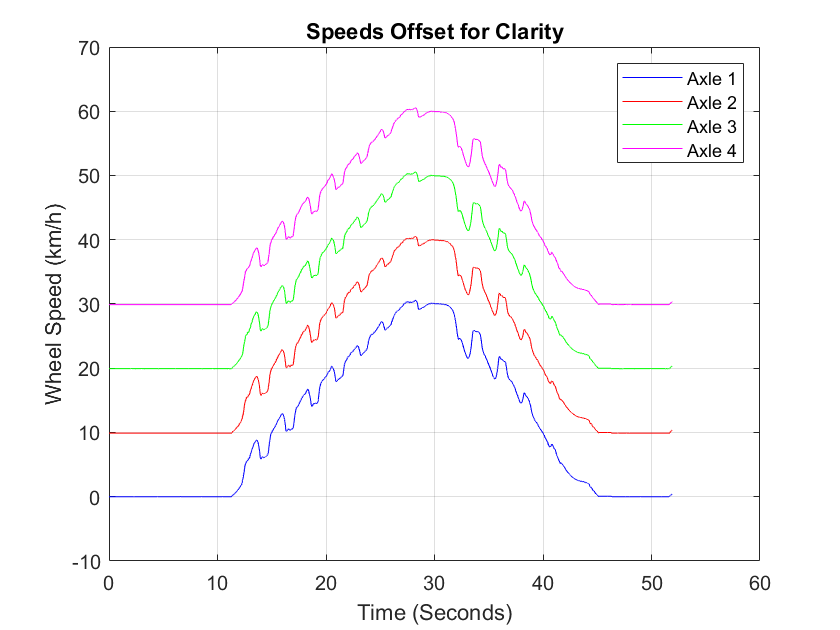

[tspan(2), tmp1, tmp2] = ginput(1);


close;

**Calculate Spin/Slide Control Efficiency (manual)**

figure('Name','Speed & Acceleration','NumberTitle','off');
subplot (2,1,1)
plot(Time, Axel_1_speed,'b');      %   plot all 4 speeds to select start/stop points
hold on;
plot(Time, Axel_2_speed + 10 , 'r');
plot(Time, Axel_3_speed + 20 , 'g');
plot(Time, Axel_4_speed + 30 , 'm');

set(gca,'Xlim',[tspan(1),tspan(2)]); 
grid;
xlabel('Time (Seconds)')
ylabel('Wheel Speed (km/h)')
legend('Axle 1','Axle 2','Axle 3','Axle 4')
title('Wheel Speeds (Speeds Offset for Clarity)')

subplot (2,1,2)
plot(Time,Accelerometer,'r','LineWidth',2);         %   plot accelerometer data
set(gca,'Xlim',[tspan(1),tspan(2)]); 
grid;
xlabel('Time (Seconds)')
ylabel('LP Filtered Deceleration')
hold off;

% figure('Name','Speed & Acceleration','NumberTitle','off');

plot(Time,Accelerometer,'r','LineWidth',2);                      %   plot accelerometer data
hold on;
xlabel('Time (Seconds)')
ylabel('LP Filtered Deceleration')
set(gca,'Xlim',[tspan(1),tspan(2)]);              %   set time span to previously selected
set(gca,'Ylim',[0,2.0]); % see entire plot
grid;

disp('Please pick available adhesion points');                      %   pick points

Please pick available adhesion points


disp('Left mouse button picks points - please go left to right!');

Left mouse button picks points - please go left to right!


disp('Right mouse button picks the last point.');

Right mouse button picks the last point.


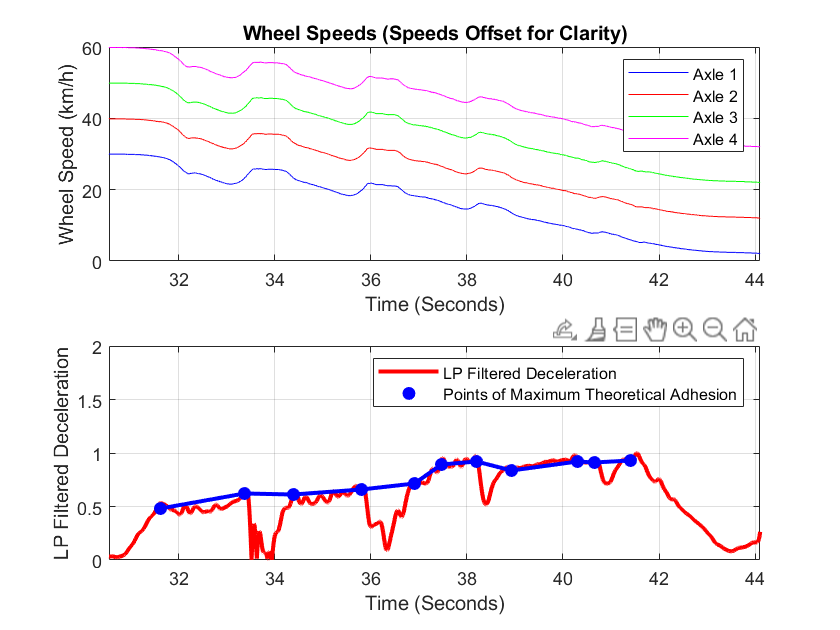

xy = [];
n = 1;
last_click = 1;
while last_click == 1                                  %   third value:   1==left, 3==right mouse button
    [xi,yi,last_click] = ginput(1);
    plot(xi,yi,'bo','MarkerFaceColor','b');
    n = n+1;
    xy(n,1) = xi;
    xy(n,2) = yi;
    if n>2
       line([xy(n-1,1),xy(n,1)],[xy(n-1,2),xy(n,2)],'Color','b','LineWidth',2)
       % connect points with blue line
    end
end

legend('LP Filtered Deceleration','Points of Maximum Theoretical Adhesion')
first_picked_point=xy(2,1);
last_picked_point=max(xy(:,1));
n=n+1;
xy(1,1) = first_picked_point;
xy(1,2) = xy(2,2);
xy(n,1) = last_picked_point;
xy(n,2) = xy(n-1,2);
hold off;

% close;          %   closure of the window may be commented out if inspection of selected points is desired

S_adh=0;
% Trapezbereich S= 1/2(a + b)h
for i=1:n-1
    S_adh = S_adh + ((xy(i+1,1)-xy(i,1)) * (xy(i,2)+xy(i+1,2)))/2;
end
%   Set left/right boundaries for actual effort calculation
S_act=0;
k=1;
% define time interval - k begining at first selected point 
while Time(k)<first_picked_point
    k=k+1;
end
m=1;
% define time interval - m end at first selected point
while Time(m)<last_picked_point
    m=m+1;
end

for i=k:m-1
    S_act = (S_act + (double((Time(i+1)-Time(i))) * (Accelerometer(i) + Accelerometer(i + 1))/2));
end

slide_efficiency = S_act/S_adh;
fprintf('Spin Slide Efficiency: %.4f', slide_efficiency)

Spin Slide Efficiency: 0.8758

Calculate Spin/Slide Control Efficiency (auto) - the same time as in manual

AccelLength = length(Accelerometer); 
SearchRange = 50;
PeakLocations = zeros(AccelLength,1);

[startTime, startIndex] = min(abs(Time.' - tspan(1)));
[endTime, endIndex] = min(abs(Time.' - tspan(2)));

for i = startIndex + SearchRange:endIndex-SearchRange
    
    PeakCheck = 1;
    
    for j = i - SearchRange:i + SearchRange
        if Accelerometer(i) < Accelerometer(j)
            PeakCheck = 0;
        end
    end
    
    if PeakCheck == 1
        PeakLocations(i) = Accelerometer(i);
    end
end


AccelAverage = mean(Accelerometer);
PeakLocations(PeakLocations <= AccelAverage) = NaN;
PeakLocations(PeakLocations <= 0) = NaN;

PeakTimeLocations = find(PeakLocations > AccelAverage);


min(PeakTimeLocations);
max(PeakTimeLocations);


TimeCut = Time(min(PeakTimeLocations)-200:max(PeakTimeLocations)+200);
AccelCut = Accelerometer(min(PeakTimeLocations)-200:max(PeakTimeLocations)+200);
PeakCut = PeakLocations(min(PeakTimeLocations)-200:max(PeakTimeLocations)+200);

figure;
plot(TimeCut, AccelCut,'b');
hold on;
scatter(Time, PeakLocations, 10, 'fill', 'r');

xlabel('Time (Seconds)')
ylabel('LP Filtered Deceleration')
grid;

close
% for m = 1:length(PeakTimeLocations)
%     xy(m,1) = PeakTimeLocations(m)
%     xy(m,2) = PeakLocations(PeakTimeLocations(m))
%     n = m;
% end
xy = [PeakTimeLocations, PeakLocations(PeakTimeLocations)];
% first_picked_point = xy(1,1)
% last_picked_point = xy(length(xy),1)

S_adh=0;

% Trapezbereich S= 1/2(a + b)h
[lengthX, lengthY] = size(xy);
for i=1: lengthX-1
    S_adh = S_adh + ((xy(i+1,1)-xy(i,1)) * (xy(i,2)+xy(i+1,2)))/2;
end
%   Set left/right boundaries for actual effort calculation

S_act = 0;
for i= xy( 1 ,1):xy( end ,1) -1
    S_act = (S_act + (1 * (Accelerometer(i) + Accelerometer(i + 1))/2));
end
slide_efficiency = S_act/S_adh;
fprintf('Spin Slide Efficiency: %.4f', slide_efficiency)

Spin Slide Efficiency: 0.8048